University Of Idaho Engine Simulation

Uses "Two Zone" Combustion Analysis With Variable Specific Heats Ratios

Only Models The Compression And Expansion Strokes

clear all;
close all;
clc;
%_________________________________________________________________________
%Engine Inputs
Load = 0.3;         % Engine Load (Affects Inlet Pressure)
RPM = 7800;         % Revolutions Per Minute [1/min]
L = (36/1000);      % Stroke of Engine [m]
B = (41.8/1000);    % Bore of Engine [m]
l = (48.8/1000);    % Length of Engine Connecting Rod [m]
N_cyl = 1;          % Number of Cylinders [unitless]
C_r = 8;            % Compression Ratio [unitless]
N_r = 2;            % Number of Revolutions Per Power Stroke
theta_b = 55;       % Combustion Burn Duration [degrees]
theta_0 = 170;      % Crank Angle At Start of Combustion [degrees]
theta_f = theta_0+theta_b; %Final Comb. Angle [degrees] 
IVC = 0;            % Time [degrees] when Intake Valve Closes
EVO = 314;          % Time [degrees] when Exhaust Valve Opens

%_________________________________________________________________________

% Engine Calculations Based On Previous Inputs
% Assumes Average Surface Area In Which Heat Transfer Occurs

A_p = (pi/4)*B^2;               %Cross Sectional Piston Area [m^2]
A_ch = 2*A_p;                   %Cylinder Head Surface Area (in chamber)
V_d = N_cyl*A_p*L;              %Displaced Volume Of Engine [m^3]
N = RPM/60;                     %Converts RPM to RPS [1/s]
S_bar_p = 2*L*N;                %Calculates Mean Piston Speed [m/s]
a = L/2;                        %Calculates Crank Radius (1/2 stroke)[m]
V_TDC = (V_d/(C_r-1))/N_cyl;    %Calculates Clearance Volume [m^3]
V_BDC = (V_d/N_cyl)+V_TDC;      %Cyl. Volume At BDC [m^3]


Calculating Losses Due To Friction fmep (obtained from Blair) Based On Displacement, RPM

% if V_d>500*10^(-6)
%     fmep=(100000+350*L*RPM)*10^(-3);
% end
% if V_d<500*10^-6
%     fmep=(100000+100*(500-V_d*10^(-6))+350*L*RPM)*10^(-3);
%end
%For Motorcycles, Use "Rolling" Bearings (For Automobiles, Use Previous)
fmep = (250*L*RPM)*10^-3;

% Volumetric Efficiency Correction Factor
CF = correction( Load,RPM );

%Initial Preallocation Of Matrices (Second Preallocation In Loops Needs To 
%Be Included (Do Not Delete)
V(1:360)=zeros;DV(1:360)=zeros;rho(1:360)=zeros;mu(1:360)=zeros;
C_k(1:360)=zeros;C_R(1:360)=zeros;X(1:360)=zeros;M_F(1:360)=zeros;
DX(1:360)=zeros;Re(1:360)=zeros;Nus(1:360)=zeros;h_g(1:360)=zeros;
DQ_w(1:360)=zeros;DQ(1:360)=zeros;Q(1:360)=zeros;DT(1:360)=zeros;
DP(1:360)=zeros;P(1:360)=zeros;T(1:360)=zeros;W_dot(1:360)=zeros;
W(1:360)=zeros;T_indicated(1:2)=zeros;Q_dot(1:360)=zeros;u(1:360)=zeros;
du(1:360)=zeros;cv(1:360)=zeros;m_b(1:360)=zeros;m_u(1:360)=zeros;
V_u(1:360)=zeros;V_b(1:360)=zeros;T_u(1:360)=zeros;T_b(1:360)=zeros;
A_u(1:360)=zeros;A_b(1:360)=zeros;DT_u(1:360)=zeros;gamma_u(1:360)=zeros;
u_u(1:360)=zeros;du_u(1:360)=zeros;cv_u(1:360)=zeros;DQ2(1:360)=zeros;
DQ_w2(1:360)=zeros;Q2(1:360)=zeros;

%_________________________________________________________________________

%Fuel Inputs/Efficiencies

AF_ratio_stoich = 15.09;   %Gravimetric Air Fuel Ratio (Stoich)
AF_ratio_mol_sotich=14.7;  %Molar Air_Fuel Ratio (Stoich)
lambda = .99;              %Excess Air Coefficient 
AF_ratio_ac = lambda*AF_ratio_stoich; %Actual Air Fuel Ratio
AF_ratio_mol=lambda*AF_ratio_mol_sotich;
LHV = 44.6e6;              %Lower Heating Value Of Fuel Mixture [J/kg]
eta_combmax = .95;         %Assumed MAX COmb. Efficiency

%Predicts Combustion Efficiency (Reference To Blair)

eta_comb=eta_combmax*(-1.6082+4.6509*lambda-2.0764*lambda^2);


Atmospheric Inputs

P_atm = 101325;         % [Pa]
T_atm = 290;            % [K]
P_BDC = Load*P_atm;     % [Pa] Inlet Pressure Moscow,ID
R_air = 287;            % [J/kg-K] Gas Constant For Air 
gamma(1:360) = 1.4;     % [-] Preallocate Gamma Array (sets initial value)
T_w =350;               % [K] Assumed Wall Temperature (Reference Stone)

________________________________________________________________________

% Polynomials Used To Calculate Gamma As A Function Of RPM
a_1 = .692;     
a_2 = 39.17e-06;    
a_3 = 52.9e-09; 
a_4 = -228.62e-13;
a_5 = 277.58e-17;
b_0 = 3049.33;  
b_1 = -5.7e-02; 
b_2 = -9.5e-05; 
b_3 = 21.53e-09;
b_4 = -200.26e-14;
c_u = 2.32584;  
c_r = 4.186e-03;
d_0 = 10.41066; 
d_1 = 7.85125;  d_3 = -3.71257;e_0 = -15.001e03;   
e_1 = -15.838e03;   e_3 = 9.613e03;f_0 = -.10329;  f_1 = -.38656;  
f_3 = .154226;  f_4 = -14.763;  f_5 = 118.27;   f_6 = 14.503;
r_0 = -.2977;   r_1 = 11.98;    r_2 = -25442;   r_3 = -.4354;


_____________________________________________________________________

R=R_air/1000;
for k = 1:2
%Corrects Temperature Based On Exhaust Gas Residuals
if k==1
    T_BDC = T_atm;            %Assumed Inlet Temperature [K]
else
    T_BDC=T_corr;
end

% Calculate Mass of Air In Cylinder/ Mass Of Fuel Based On AFR
rho_a = P_BDC/(R_air*T_BDC);    %Air Density kg/m^3
m_a = rho_a*V_d;                %Mass of Air In Cylinder [kg]
m_f = m_a/AF_ratio_ac;          %Mass Of Fuel In Cylinder [kg]
m_c = m_a+m_f;                  %Mass In Cylinder

%Specifying Initial Conditions For Loops
%DV,DX,etc. Are Relative To Change In Theta (i.e. DV/Dtheta)

theta(1:360)=zeros; %Starting Crank Angle [deg]
V(1:360)=zeros;     %Preallocate Volume Array
V(1)=V_BDC;         %Starting Combustion Chamber Volume [m^3]
DV(1:360) = zeros;  %Preallocate Change In Volume Array
DV(1) = 0;          %Specifying Initial Change In Volume [m^3}
P(1:360)=P_BDC;     %Preallocate Pressure Array
DP(1:360) = zeros;  %Specifying Initial Change In Pressure
T(1:360)=zeros;     %Preallocate Temperature Array
T(1) = T_BDC;       %Inlet Temperature [K]
T_u(1)=T_BDC;       %Initial Unburned Temperature[K]
DT(1:360) = zeros;  %Specifying Initial Change In Temperature
DT_u(1:360)=zeros;  %Preallocate Change In Unburned Temperature
gamma(1)=1.4;       %Initial Gamma Input
gamma_u(1)=1.4;     %Initial Gamma Input
X(1:360) = 0;       %Preallocate Mass Burn Array
DX(1:360) = zeros;  %Preallocate Change In Mass Burn Fraction [unitless]
DQ(1:360) = zeros;  %Preallocate Heat Release Array
DQ2(1:360)=zeros;   %Preallocate Two Zone Heat Release Array
Q(1:360)=zeros;     %Preallocate Heat Array
Q2(1:360)=zeros;    %Preallocate 2 zone Heat Array
M_F(1:360) = 0;     %Preallocate Mass In Comubstion Chamber Array 
rho(1:360) = zeros;    %Preallocates Ideal Gas Law array
rho(1) = P(1)/(R_air*T(1)); %Initial Value Ideal Gas Array
mu(1:360)=zeros;     %Preallocate Viscosity Array
mu(1)=7.457*10^(-6)+4.1547*10^(-8)*T_BDC-7.4793*10^(-12)*T_BDC^(2);
C_k(1:360)=zeros;   %Preallocate Thermal COnductivity Array   
C_k(1) = 6.1944*10^(-3)+7.3814*10^(-5)*T_BDC-1.2491*10^(-8)*T_BDC^(2);
C_R(1:360) = zeros; %Preallocate Radiation Coefficient Array
C_R(1) = 4.25*10^(-09)*((T(1)^4-T_w^4)/(T(1)-T_w)); %Initial Rad. Coeff
Re(1:360)=zeros;    %Preallocate Reynolds Value Array
Re(1)=rho(1)*S_bar_p*B/mu(1); %Initial Reynolds Value
Nus(1:360)=zeros;   %Preallocating Nusselt Number Array
Nus(1)=.49*Re(1)^(.7);  %Initial Nusselt Number
h_g(1:360)=zeros;   %Preallocate Heat Transfer Coefficient Array
h_g(1)=C_k(1)*Nus(1)/B; %Initial Heat Transfer Coefficient
s(1:360)=zeros;     %Preallocates Distance Crank/Piston Axes Array
s(1) = -a*cosd(theta(1))+sqrt(l^2 - a^2*sind(theta(1))^2);%Initial Val.
W(1:360) = zeros;   %Preallocate Work Array
W_dot(1:360) = zeros; %Preallocate Power Array
T_indicated(1:360) = zeros; %Preallocate Torque Array
Q_dot(1:360) = zeros; %Preallocate Heat Transfer Array
u(1:360) = zeros;   %Preallocate Internal Energy Array
du(1:360) = zeros;  %Preallocates Change In Internal Energy Array
cv(1:360) = zeros;  %Preallocates Heat Capacity Array
DQ_w(1:360)=zeros;  %Preallocate Convective Heat Loss Array
DQ_w2(1:360)=zeros; %Preallocate Convective Heat Loss Array 2 zone
m_b(1:360)= zeros;  %Preallocate mass burned array
m_u(1:360)=m_c;     %Preallocate unburned mass array
V_u(1:360)=zeros;   %Preallocate unburned Volume Array
V_u(1) = V(1);      %Initial Unburned Volume

%________________________________________________________________________
theta=1:360;

for i = 2:360  
    %Specifies Distance Between Crank/Piston Axes As A Function Of theta
    s = -a*cosd(theta(i))+sqrt(l^2 - a^2*sind(theta(i))^2);
    %Specifies Volume As A Function Of Crank Angle
    V(i) = V_TDC +((pi/4)*B^2)*(l + a - s);
    %Specifies Change In Volume As A Function Of Crank Angle
    DV(i) = V(i)-V(i-1);  
    %Calculates Density As A Function Of Crank Angle
    rho(i) = P(i-1)/(R_air*T(i-1));
    %Calculates Viscosity As A Function Of Temperature
    mu(i)=7.457*10^(-6)+4.1547*10^(-8)*T(i-1)-7.4793*10^(-12)*T(i-1)^(2);
    %Calculating Instantaneous Thermal Conductivity of Cylinder Gas
    C_k(i) = 6.1944*10^(-3)+7.3814*10^(-5)*T(i-1)-1.2491*10^(-8)*T(i-1)^(2);
    %Calculating The Radiation Heat Transfer Coefficient
    C_R(i) = 4.25*10^(-09)*((T(i-1)^4-T_w^4)/(T(i-1)-T_w));
    %Instantaneous Suface Area (For Heat Transfer)
    A = A_ch + A_p + pi*B*(l+a-s);
    if i<=2
        A_u=A;
    end
      
   %_____________________________________________________________________
   
    %Specifies Mass Fraction Burn As A Function Of Crank Angle (Weibe Fcn.)
    %Also Specifies Mass Of Fuel In Combustion Chamber As A Function Of
    %Theta
    
       if theta(i)<theta_0
            X(i)=0;
        else
        X(i) = 1-exp(-5*((theta(i)-theta_0)/theta_b)^3);
        if theta(i) < theta_f 
              M_F(i) = V(theta_0-1)*rho(theta_0-1)/(lambda*AF_ratio_mol);
        end
       end
        
    %____________________________________________________________________
    %Specifies Change In Mass Fraction Burn As A Function Of Crank Angle
    DX(i) = X(i) - X(i-1);
    
    %____________________________________________________________________
    
    %Incorporating The Annand Method To Predict Heat Transfer
    %Calculating Reynolds Number
    Re(i)=rho(i)*S_bar_p*B/mu(i);
    %Calculating Nusselt Number (constant=.26 two stroke, .49 4 stroke)
    Nus(i)=.49*Re(i)^(.7);
    %Calculating Heat Transfer Coefficient Using Annand Method
    h_g(i)=C_k(i)*Nus(i)/B;
    %Calculates Convective Losses Into Wall As A Function Of Crank Angle
    DQ_w(i) = (h_g(i)+C_R(i))*A*(T(i-1)-T_w)*(60/(360*RPM));
    %Calculates Change In Heat Transfer (total) As A Function Of Crank
    %Angle
    DQ(i) = eta_comb*LHV*M_F(i)*DX(i)-DQ_w(i);
    %Calculates Total Heat Transfer (Per Cycle)
    Q(i) = Q(i-1)+DQ(i);     
    %____________________________________________________________________
    
    %Specifies Pressure and Temperature Increases Between Intake Valve
    %Closing and Exhaust Valve Opening
    if IVC< theta(i) 
        DT(i)=T(i-1)*(gamma(i-1)-1)*((1/(P(i-1)*V(i-1)))*DQ(i)-(1/V(i-1))*DV(i));
        DP(i)=(-P(i-1)/V(i-1))*DV(i)+(P(i-1)/T(i-1))*DT(i);
        P(i) = P(i-1)+DP(i);
    end
    if EVO < theta(i)
        P(i) = P_atm;
    end
    if 200 < theta(i)
      if P(i)<=P_atm
        P(i)=P_atm;
      end
    end
    %____________________________________________________________________
    %Calculate Burned, Unburned Mass Fractions
    m_b(i) = m_b(i-1)+DX(i)*m_c;    %Burned Mass
    m_u(i) = m_u(i-1)-DX(i)*m_c;    %Unburned Mass
    %Calculating Burned, Unburned Volumes
    if theta(i)<=theta_0
        V_u(i)=N_cyl*V(i);
    end
    if theta(i)>theta_0
    V_u(i)=((m_u(i)*V_u(i-1))/m_u(i-1))*(P(i)/P(i-1))^(-1/gamma_u(i-1));
    end
    V_b(i)=N_cyl*V(i)-V_u(i);
    if V_b(i)<0
        V_b(i)=0;
    end
    %Calculating Burned, Unburned Temperatures
    T_u(i)=P(i)*V_u(i)/(m_u(i)*R*1000);
    if theta(i) <= theta_0+4
        T_b(i)=0;
    end
    if theta(i)>theta_0+4
        T_b(i)=P(i)*V_b(i)/(m_b(i)*R*1000);
    end

    %Calculate Unburned, Burned Areas Based On Volume Ratio
    A_u(i)=A*(1-sqrt(X(i)));
    A_b(i)=A*(X(i)/sqrt(X(i)));
    DT_u(i)=T_u(i)-T_u(i-1);    

    %____________________________________________________________________
    %Returns Temperature Values To Beginning Of Loop
    %Assumes Temperature Drops Back To ATM Temp After Exhaust Is Extracted
    T(i) = T(i-1)+DT(i);
    %Calculate The Residual Gas Fraction 
    %Assume A Polytropic Constant Of 1.3
    R_frac = (1/C_r)*(P_BDC/P_atm)^(1/1.3)*(1/lambda);
    %Calculates Cylinder Work [J] As A Function Of Crank Angle
    %Treats Atmospheric Pressure As Reference State
    W(i) = W(i-1)+(P(i)-P_atm)*DV(i);
    %Calculates Power [kW] As A Function Of Crank Angle
    W_dot(i)=(N_cyl*W(i)*N/N_r)/1000;
    %Indicated Mean Effective Pressure
    imep = CF*W_dot(360)*N_r*1000/(V_d*1000*N);
    %Calculates Torque[N*m] As A Function Of Crank Angle
    T_indicated(i) = (W_dot(i)*1000)/(2*pi*N);
    %Calculates Heat Loss [kW] As A Function Of Crank Angle
    Q_dot(i) = (N_cyl*Q(i)*N/N_r)/1000;
    
    %____________________________________________________________________
    % The Following Section Of Code Calculates An Updated Value Of Gamma
    % Using The "Polynomial Method" Developed By Krieger-Borman
    % User Of This Code Must Be Careful Because Accuracy Of This Method
    % Drops As The Fuel Mixture Becomes Increasingly Rich
    
    %Calculates A,B Factors For Following Block Of Code
    A_t = a_1*T(i)+a_2*T(i)^2+a_3*T(i)^3+a_4*T(i)^4+a_5*T(i)^5;
    A_tu = a_1*T_u(i)+a_2*T_u(i)^2+a_3*T_u(i)^3+a_4*T_u(i)^4+a_5*T_u(i)^5;
    B_t = b_0+b_1*T(i)+b_2*T(i)^2+b_3*T(i)^3+b_4*T(i)^4;
    B_tu = b_0+b_1*T_u(i)+b_2*T_u(i)^2+b_3*T_u(i)^3+b_4*T_u(i)^4;
    %Calculates Factor "D" As A Function Of lambda
    D_lambda = d_0 + d_1*lambda^(-1)+ d_3*lambda^(-3);
    %Calculates Factor "F" As A Function Of Temperature,lambda
    E_TLambda = (e_0 + e_1*lambda^(-1)+ e_3*lambda^(-3))/T(i);
    E_TLambdau = (e_0 + e_1*lambda^(-1)+ e_3*lambda^(-3))/T_u(i);
    F_TPLambda = (f_0 + f_1*lambda^(-1) + f_3*lambda^(-3) + ...
        ((f_4 + f_5*lambda^(-1))/T(i)))*log(f_6*P(i));
    F_TPLambdau = (f_0 + f_1*lambda^(-1) + f_3*lambda^(-3) + ...
        ((f_4 + f_5*lambda^(-1))/T_u(i)))*log(f_6*P(i));    
    %Calculates Correction Factor For Internal Energy
    u_corr = c_u*exp(D_lambda +E_TLambda + F_TPLambda);
    u_corr_u=c_u*exp(D_lambda +E_TLambdau + F_TPLambdau);
    %Calculates Internal Energy As A Function Of Crank Angle
    u(i) = A_t - B_t/lambda + u_corr;
    u_u(i) = A_tu - B_tu/lambda + u_corr_u;
    %Calculates Change In Internal Energy
    du(i) = u(i) - u(i-1);
    du_u(i) = u_u(i) - u_u(i-1);
    %Calculates Heat Capacity "C_v" As A Function Of Crank Angle
    cv(i) = du(i)/DT(i);
    cv_u(i)=du_u(i)/DT_u(i);
    %Calculates Correction Factor For "R" Value As A Function Of Crank
    %Angle
    R_corr = c_r*exp(r_0*log(lambda) + (r_1+r_2/T(i) + ...
        r_3*log(f_6*P(i)))/lambda);
    R_corr_u = c_r*exp(r_0*log(lambda) + (r_1+r_2/T_u(i-1) + ...
        r_3*log(f_6*P(i)))/lambda);
    %Calculates Actual "R" Value
    R = .287 + .020/lambda + R_corr;
    R_u = .287 + .020/lambda + R_corr_u;
    %Calculates Actual Gamma Value And Returns To Beginning Of Code
    gamma_u(i)=1+R_u/cv_u(i);
    gamma(i) = 1 + R/cv(i);
        if gamma(i)<1.2
            gamma(i)=1.4;
            gamma_u(i)=1.4;
        end

    if theta(i)>=EVO
        gamma(i)=1.4;
        gamma_u(i)=1.4;
    end

%________________________________________________________________________

    %Calculate Temperature Of Exhaust Based On Polytropic Relations
    if EVO < theta(i)
    T(i)=T(EVO)*(P_BDC/P(EVO))^((gamma(i)-1)/gamma(i));
    T_b(i)=T_b(EVO)*(P_BDC/P(EVO))^((gamma(i)-1)/gamma(i));
    end     
end
%Calculates A Corrected Inlet Temperature Based On EGR
T_corr = R_frac*T(360)+(1-R_frac)*T_BDC;
% T_corr = T_BDC;
end
%________________________________________________________________________

%Specified Outputs (On Matlab Screen)
W_dot_indicated=W_dot(360);
bmep = imep-fmep;
W_dot_ac = (bmep*V_d*1000*N/(N_r*1000))

W_dot_ac = 0.4157

T_ac = W_dot_ac/(2*pi*N*10^(-3))

T_ac = 0.5090


%Calculated Mechanical Efficiency (Based On Previous Inputs)
eta_m = bmep/imep;   %Calculates Mechanical Efficiency

%________________________________________________________________________

%Calculates Brake Specific Fuel Consumption
m_ta = P_BDC*V_d/(R_air*T_BDC);        %Calculate Trapped Air In Cylinder
eta_v = CF*((m_ta)/(rho_a*V_d));       %Corrected Volumetric Efficiency 
m_dot_f = N_cyl*M_F(theta_0)*(N/N_r);  %Mass Flow Rate Of Fuel
m_dot_a = AF_ratio_ac*m_dot_f;         %Mass Flow Rate Of Air
BSFC = (m_dot_f*1000*3600)/(W_dot_ac) %BSFC [g/kW*h]

BSFC = 683.9365

eta_f = 3600/(BSFC*(LHV*10^(-6)));     %Fuel Conversion Efficiency

%Calculate Emissions

T_NO=.90*max(T_b);                          %Calculate Avg. Burn Temp
P_NO=max(P);                                %Assuming Pressure is peak
P_EXH=(P(EVO)+P_atm)/2;                     %Calculating Exhaust Press.
[ PPM_NO ] = NOX( T_NO,P_atm,lambda,P_NO,T_BDC,P_BDC,P_EXH)

PPM_NO = 849.2069

P_peak = max(P);                            %Peak Pressure
disp('Percentage of Fuel Mass Reaching Exhaust')

Percentage of Fuel Mass Reaching Exhaust


[ HC ] = hydrocarbons( R_frac,AF_ratio_ac,B,P_peak,imep,C_r,V_d,N_cyl,T_w,N );
HC = 100*HC

HC = 16.1784


%Calculate brake specific emissions

[ w_NO ] = BSNOX( T_NO,P_atm,lambda,P_NO,T_BDC,P_BDC,P_EXH);
m_dot_NO = w_NO*(m_dot_a+m_dot_f);
BSNOX = (m_dot_NO*1000*3600)/(W_dot_ac) % [g/kW-h]

BSNOX = 9.7149


m_dot_HC=HC/100*m_dot_f;
BSHC=(m_dot_HC*1000*3600)/(W_dot_ac) % [g/kW-h]

BSHC = 110.6497


%________________________________________________________________________

%Specifies Conditions For Minimum and Maximum Plot Values
v_min = min(V); 
v_max = max(V);
p_min = min(P); 
p_max = max(P);
w_min = min(W_dot); w_max = max(W_dot);
T_min = min(T); T_max = max(T);
Q_min = min(Q_dot); Q_max = max(Q_dot);
Tmin = min(T_indicated); Tmax = max(T_indicated);

%________________________________________________________________________


### Plot Statements

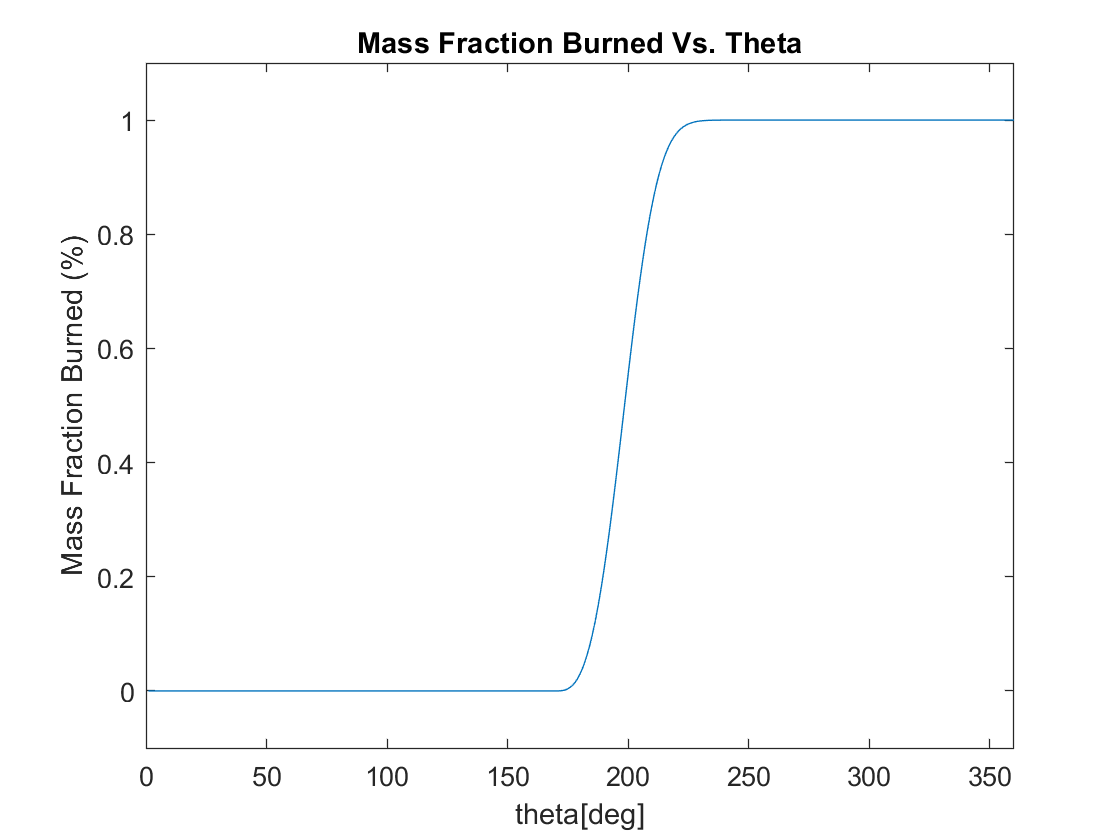


figure(1)
plot(theta,X)
title('Mass Fraction Burned Vs. Theta')
xlabel('theta[deg]')
ylabel('Mass Fraction Burned (%)')
axis([0 360 -.1 1.1])

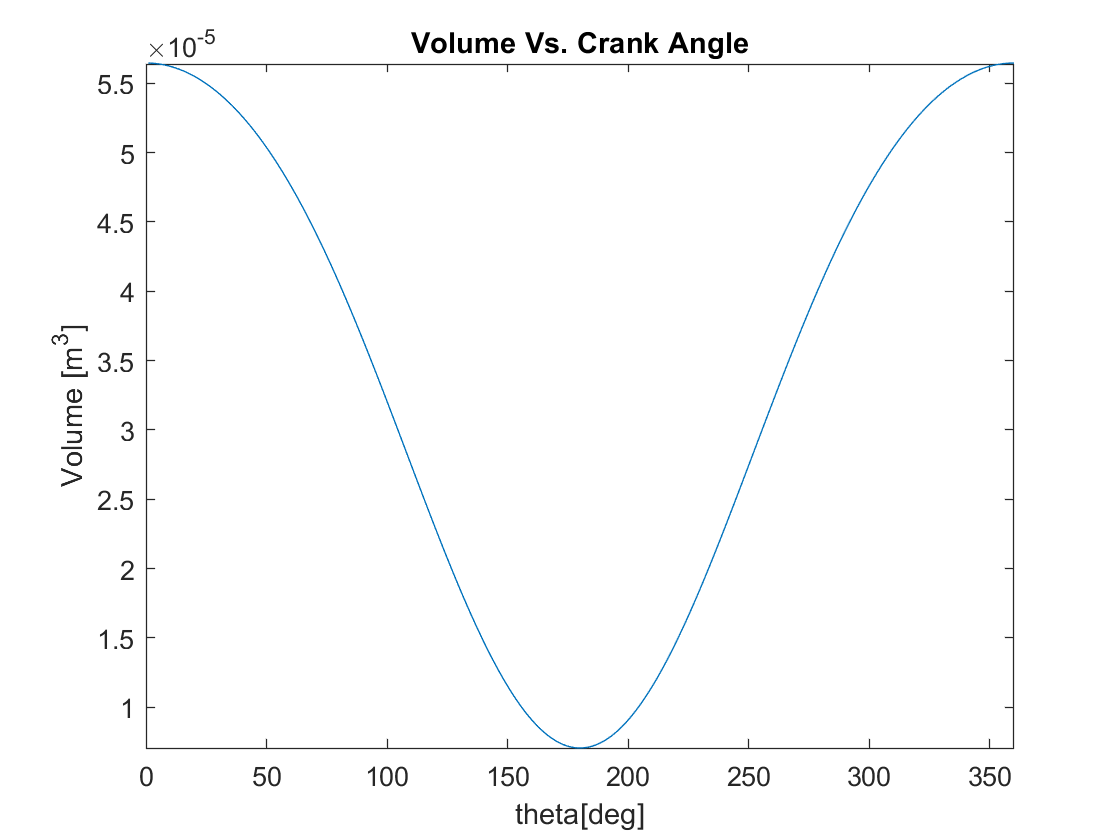

% 
 figure(2)
 plot(theta,V)
 title('Volume Vs. Crank Angle')
 xlabel('theta[deg]')
 ylabel('Volume [m^3]')
 axis([0 360 v_min v_max])

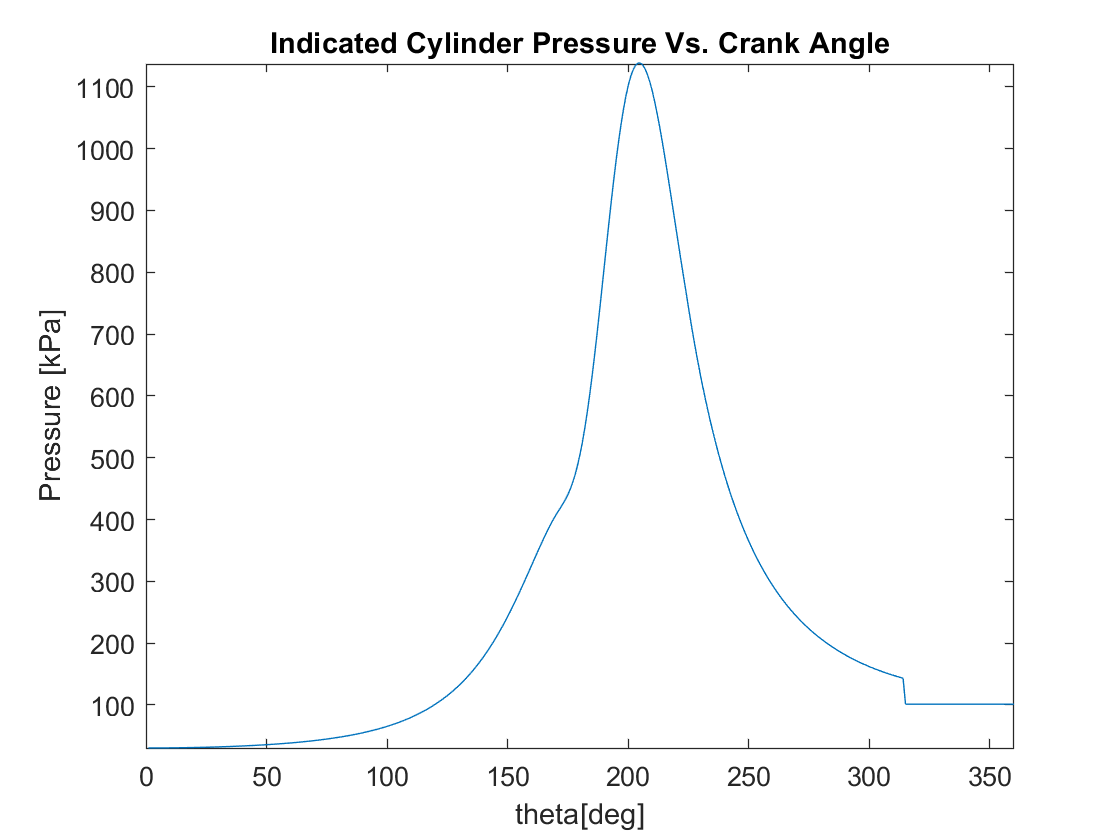

% 
 figure(3)
 plot(theta,P/1000)
 title('Indicated Cylinder Pressure Vs. Crank Angle')
 xlabel('theta[deg]')
 ylabel('Pressure [kPa]')
axis([0 360 p_min/1000 p_max/1000])

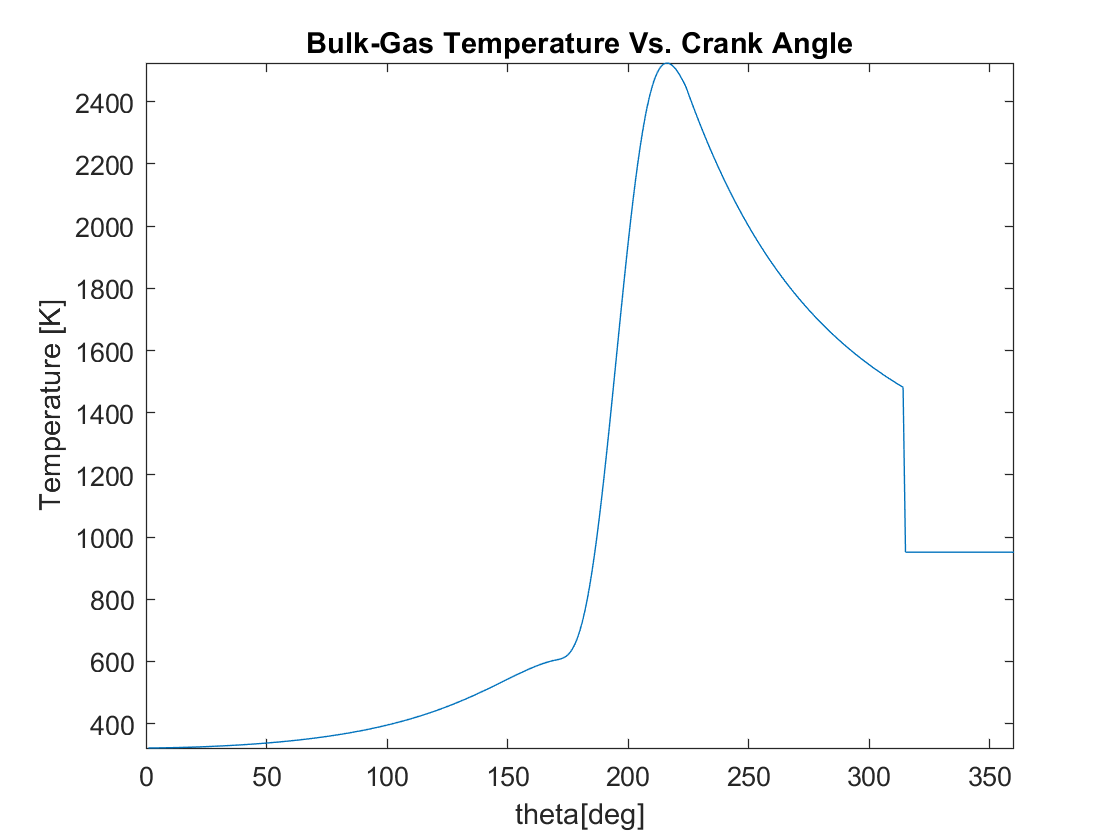

% 
figure(4)
plot(theta,T)
title('Bulk-Gas Temperature Vs. Crank Angle')
xlabel('theta[deg]')
ylabel('Temperature [K]')
axis([0 360 T_min T_max])

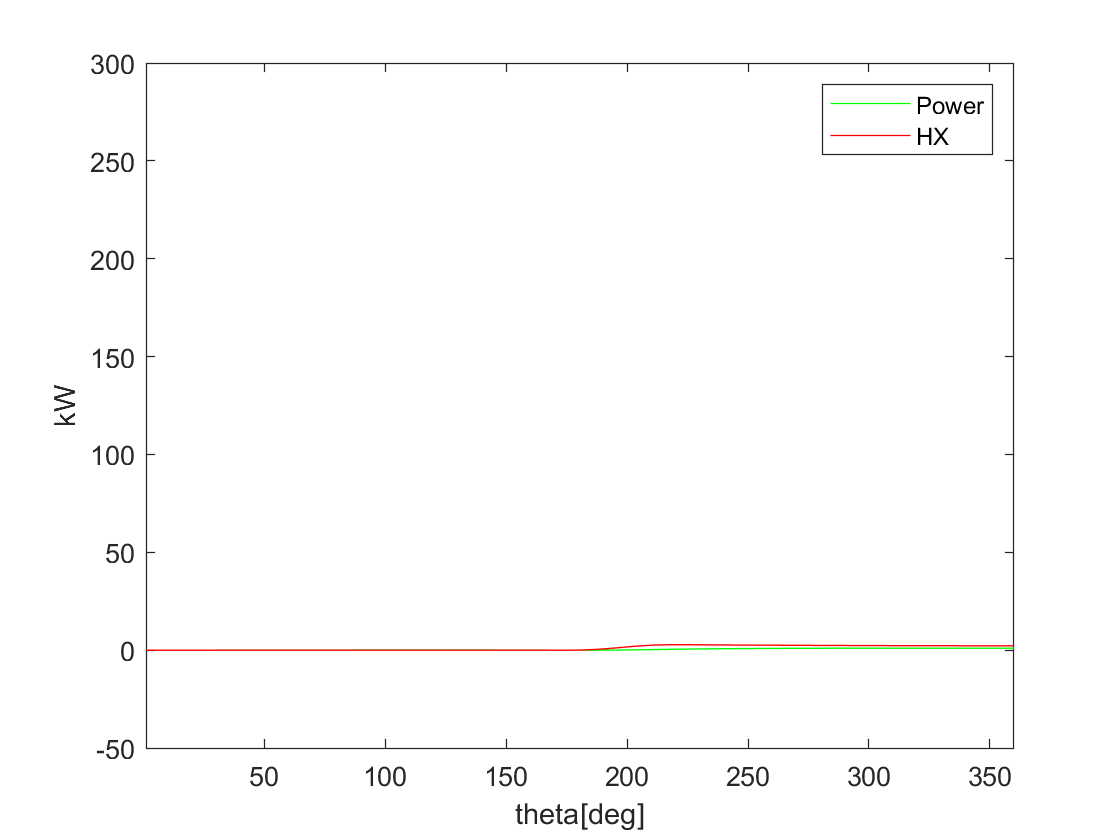

% 
 figure(5)
 title('Power and Heat Transfer')
 plot(theta,W_dot,'g')
 hold on;
 plot(theta,Q_dot,'r')
 legend Power HX
 xlabel('theta[deg]')
 ylabel('kW')
 axis([1 360 -50 300])

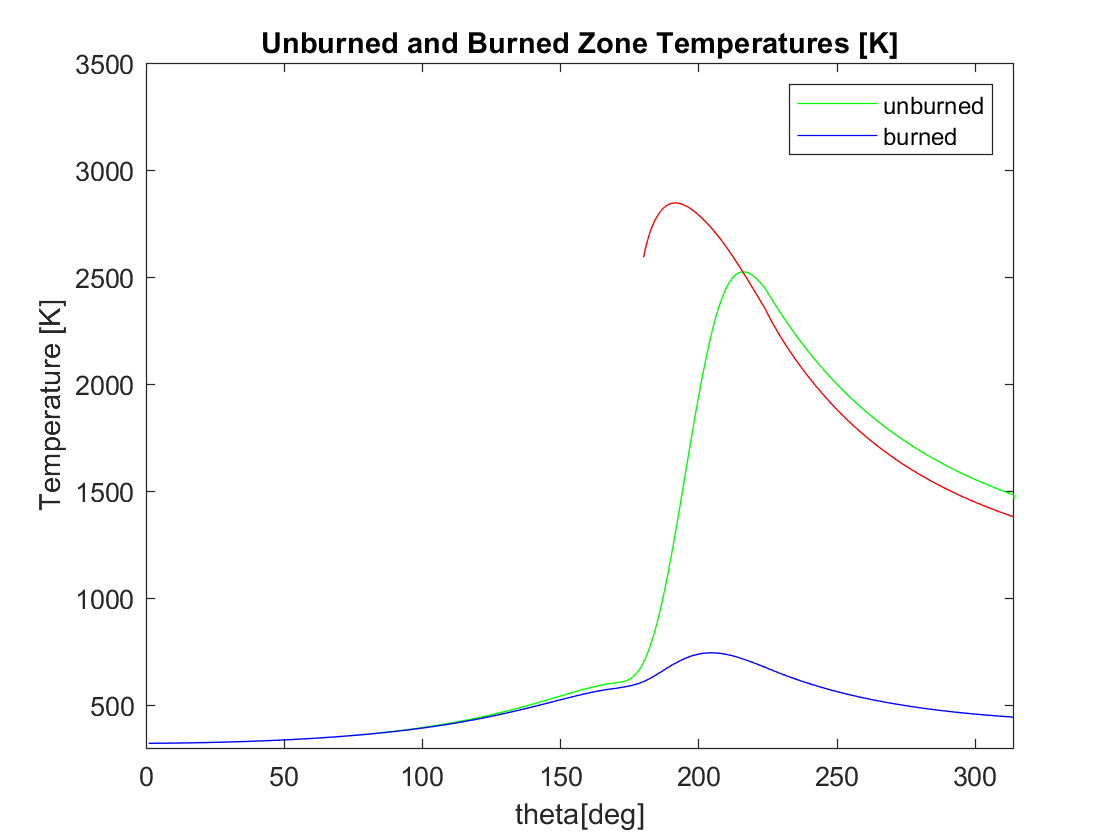

% 
figure(6)
plot(theta,T,'g')
xlabel('theta[deg]')
ylabel('Temperature [K]')
title('Unburned and Burned Zone Temperatures [K]')
hold on;
plot(theta(1:EVO),T_u(1:EVO),'b')
plot(theta(theta_0+10:EVO),T_b(theta_0+10:EVO),'r')
legend unburned burned
axis([0 EVO 300 3500])